% ========================================================================
% Stochastic Bacteria-Phage Dynamics via Gillespie SSA
% ========================================================================
%
%
% Reference: Gillespie, J. Phys. Chem. 81(25), 2340-2361 (1977).
% ========================================================================

clear; clc;

    %% ==================== Parameter Settings ====================
    % Biological parameters
    r = 1;          % Bacterial growth rate (time^-1)
    K = 1000;       % Environmental carrying capacity (individuals)
    ef_a = 0.010;
    a = ef_a / K;   % Infection rate coefficient
    alpha = 2;      % Lysis rate (time^-1)
    Omega = 50;     % Burst size (phages released per lysis event)
    delta = 0.04;   % Phage decay rate (time^-1)
    
    % Initial conditions (must be integers!)
    B0 = 100;       % Initial susceptible bacteria count
    I0 = 0;         % Initial infected bacteria count (>0 to observe lysis dynamics)
    P0 = 100;       % Initial phage count
    
    % Simulation parameters
    t_end = 500;    % Simulation end time
    n_runs = 3;     % Number of independent simulations
    
    %% ==================== Run Simulations ====================
    fprintf('Starting Gillespie stochastic simulation...\n');

Starting Gillespie stochastic simulation...


    fprintf('Parameters: r=%.2f, K=%d, a=%.4f, alpha=%.2f, Omega=%d, delta=%.2f\n', ...
            r, K, a, alpha, Omega, delta);

Parameters: r=1.00, K=1000, a=0.0000, alpha=2.00, Omega=50, delta=0.04


    fprintf('Initial state: B=%d, I=%d, P=%d\n\n', B0, I0, P0);

Initial state: B=100, I=0, P=100



    fprintf('Termination: t >= %.2f or population extinction (a0=0)\n\n', t_end);

Termination: t >= 500.00 or population extinction (a0=0)



    
    % Store results from all runs
    all_trajectories = cell(n_runs, 1);
    
    for run = 1:n_runs
        fprintf('Run %d/%d...\n', run, n_runs);
        [t, B, I, P, stop_reason] = gillespie_ssa(t_end, B0, I0, P0, r, K, a, alpha, Omega, delta);
        all_trajectories{run} = struct('t', t, 'B', B, 'I', I, 'P', P, 'stop_reason', stop_reason);
    end

Run 1/3...


  Initial total propensity a0=114.1000
  -> Complete: t=500.00, Reactions=1839178, Termination: Reached simulation end time


Run 2/3...


  Initial total propensity a0=114.1000
  -> Complete: t=500.00, Reactions=1805871, Termination: Reached simulation end time


Run 3/3...


  Initial total propensity a0=114.1000
  -> Complete: t=500.00, Reactions=1843763, Termination: Reached simulation end time


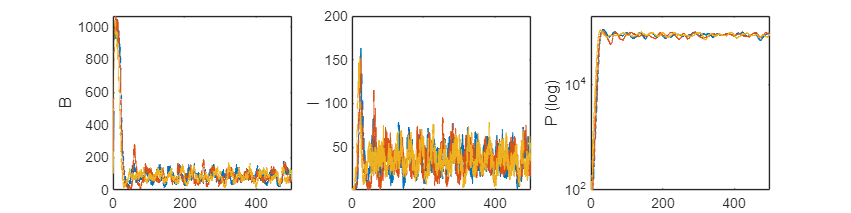

    
    %% ==================== Result Visualization ====================
    figure('Position', [100, 100, 1600, 400]); 
    colors = lines(n_runs);
    t_min_plot = 0;
    t_max_plot = 500;
    
    % Subplot 1: Susceptible Bacteria (B) - Linear scale to handle zero values
    subplot(1, 3, 1); hold on;
    for run = 1:n_runs
        traj = all_trajectories{run};
        idx_time = traj.t >= t_min_plot & traj.t <= t_max_plot;
        plot(traj.t(idx_time), traj.B(idx_time), 'Color', [colors(run,:),1], 'LineWidth', 1);
    end
    %set(gca, 'YLim', [-5, 10^3], 'YScale', 'linear');
    set(gca, 'XLim', [t_min_plot, t_max_plot]);
    ylabel('B');
    grid off; box on;
    
    % Subplot 2: Infected Bacteria (I)
    subplot(1, 3, 2); hold on;
    for run = 1:n_runs
        traj = all_trajectories{run};
        idx_time = traj.t >= t_min_plot & traj.t <= t_max_plot;
        I_plot = traj.I(idx_time);
        I_plot(I_plot == 0) = NaN; % Replace zeros with NaN to prevent breaks in log scale
        plot(traj.t(idx_time), I_plot, 'Color', [colors(run,:),1], 'LineWidth', 1);
    end
    set(gca, 'YLim', [1, 200]);
    set(gca, 'XLim', [t_min_plot, t_max_plot]);
    ylabel('I');
    box on;
    
    % Subplot 3: Phages (P)
    subplot(1, 3, 3); hold on;
    for run = 1:n_runs
        traj = all_trajectories{run};
        idx_time = traj.t >= t_min_plot & traj.t <= t_max_plot;
        P_plot = traj.P(idx_time);
        P_plot(P_plot == 0) = NaN;
        semilogy(traj.t(idx_time), P_plot, 'Color', [colors(run,:),1], 'LineWidth', 1);
    end
    set(gca, 'YLim', [10^2, 2*10^5], 'YScale', 'log');
    set(gca, 'XLim', [t_min_plot, t_max_plot]);
    ylabel('P (log)');
    box on;

    
    %% ==================== Statistical Summary ====================
    fprintf('\n=== Simulation Complete ===\n');


=== Simulation Complete ===


    for run = 1:n_runs
        traj = all_trajectories{run};
        fprintf('Run %d: Final state B=%d, I=%d, P=%d, Total reactions=%d, Termination: %s\n', ...
                run, traj.B(end), traj.I(end), traj.P(end), length(traj.t)-1, traj.stop_reason);
    end

Run 1: Final state B=70, I=25, P=91831, Total reactions=1839178, Termination: Reached simulation end time
Run 2: Final state B=65, I=29, P=87783, Total reactions=1805871, Termination: Reached simulation end time
Run 3: Final state B=80, I=40, P=87245, Total reactions=1843763, Termination: Reached simulation end time




    %% ==================== Gillespie SSA Core Function ====================


    function [t, B, I, P, stop_reason] = gillespie_ssa(t_end, B0, I0, P0, r, K, a, alpha, Omega, delta)
        % Initialization
        t = 0; B = B0; I = I0; P = P0;
        stop_reason = 'Unknown';
        
        % Preallocate memory
        max_reactions_alloc = 1e6;
        t_history = zeros(max_reactions_alloc, 1);
        B_history = zeros(max_reactions_alloc, 1);
        I_history = zeros(max_reactions_alloc, 1);
        P_history = zeros(max_reactions_alloc, 1);
        
        idx = 1;
        t_history(idx) = t; B_history(idx) = B; I_history(idx) = I; P_history(idx) = P;
        reaction_count = 0;
        
        % Initial propensity
        N = B + I;
        a0_init = r*B + (r/K)*N*B + a*B*P + alpha*I + delta*P;
        fprintf('  Initial total propensity a0=%.4f\n', a0_init);
        
        % ==================== Main Loop ====================
        while t < t_end && reaction_count < max_reactions_alloc
            % Check for complete extinction (all populations zero)
            if B == 0 && I == 0 && P == 0
                stop_reason = 'Complete extinction (a0=0)';
                break;
            end
            
            N = B + I;
            a_vec = [r*B, (r/K)*N*B, a*B*P, alpha*I, delta*P];
            a0 = sum(a_vec);
            
            if a0 == 0
                stop_reason = 'No available reactions (a0=0)';
                break;
            end
            
            r1 = rand(); r2 = rand();
            tau = (1.0 / a0) * log(1.0 / r1);
            
            % Select reaction
            cum_sum = 0; mu = 0;
            for i = 1:5
                cum_sum = cum_sum + a_vec(i);
                if cum_sum > r2 * a0
                    mu = i; break;
                end
            end
            
            t = t + tau;
            reaction_count = reaction_count + 1;
            idx = idx + 1;
            
            switch mu
                case 1, B = B + 1;
                case 2, B = max(0, B - 1);
                case 3, B = max(0, B - 1); P = max(0, P - 1); I = I + 1;
                case 4, I = max(0, I - 1); P = P + Omega;
                case 5, P = max(0, P - 1);
            end
            
            % Dynamic memory expansion (prevents array index out-of-bounds)
            if idx > max_reactions_alloc
                max_reactions_alloc = max_reactions_alloc * 2;
                t_history = [t_history; zeros(max_reactions_alloc - length(t_history), 1)];
                B_history = [B_history; zeros(max_reactions_alloc - length(B_history), 1)];
                I_history = [I_history; zeros(max_reactions_alloc - length(I_history), 1)];
                P_history = [P_history; zeros(max_reactions_alloc - length(P_history), 1)];
            end
            
            t_history(idx) = t; B_history(idx) = B; I_history(idx) = I; P_history(idx) = P;
        end
        
        % Final state assessment
        if isempty(stop_reason) || strcmp(stop_reason, 'Unknown')
            if t >= t_end, stop_reason = 'Reached simulation end time';
            else, stop_reason = 'Reached maximum reaction steps'; end
        end
        
        % Truncate output arrays
        t = t_history(1:idx); B = B_history(1:idx); I = I_history(1:idx); P = P_history(1:idx);
        fprintf('  -> Complete: t=%.2f, Reactions=%d, Termination: %s\n', t(end), reaction_count, stop_reason);
    end